clc
clear
close all

%Serena Elijah
%AE 426 Project 1   
%Question 2


r0 = [pi+0.1 0];  %Iniial conditions
tspan = 1:0.1:200 ; %Time step


Solving Differential Equation Using Ode45

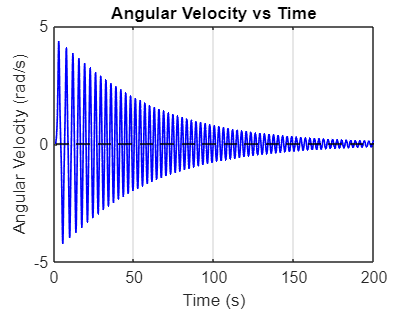

 
%Ode45 to solve differential equation using initial conditions
[ttheta,rtheta] = ode45(@(ttheta,rtheta) eome(ttheta, rtheta), tspan, r0) ;


%Plot of Angular Velocity vs Time 
figure;
plot(ttheta,rtheta(:,2),'b','LineWidth',1)
hold on 
plot(ttheta, 0*ones(size(ttheta)), 'k--', 'LineWidth', 0.5)
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocity vs Time');

grid on;

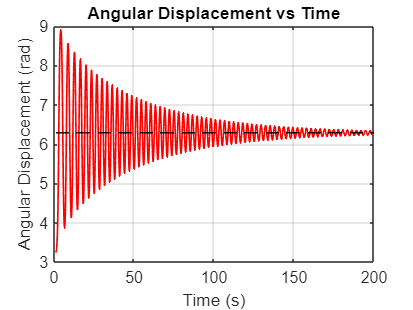



%Plot of Angular Displacement vs Time 
figure;
plot(ttheta,rtheta(:,1),'r','Linewidth',1)
hold on 
plot(ttheta, 2*pi*ones(size(ttheta)), 'k--', 'LineWidth', 0.5)
xlabel('Time (s)');
ylabel('Angular Displacement (rad)');
title('Angular Displacement vs Time');
grid on;




[~, locs_velocity] = findpeaks(rtheta(:,2));  % Find peaks of angular velocity
amplitudes_velocity = rtheta(locs_velocity, 2);  % Get the peak values of angular velocity

% Display the amplitudes and check percentage reduction
fprintf('Angular Velocity reduction per cycle:\n');

Angular Velocity reduction per cycle:


for i = 1:length(amplitudes_velocity)-1
    reduction_velocity = (amplitudes_velocity(i) - amplitudes_velocity(i+1)) / amplitudes_velocity(i) * 100;
    fprintf('Cycle %d to %d: %.2f%% reduction\n', i, i+1, reduction_velocity);
end

Cycle 1 to 2: 6.18% reduction
Cycle 2 to 3: 5.86% reduction
Cycle 3 to 4: 5.63% reduction
Cycle 4 to 5: 5.91% reduction
Cycle 5 to 6: 5.57% reduction
Cycle 6 to 7: 5.81% reduction
Cycle 7 to 8: 5.36% reduction
Cycle 8 to 9: 5.66% reduction
Cycle 9 to 10: 5.25% reduction
Cycle 10 to 11: 5.47% reduction
Cycle 11 to 12: 5.60% reduction
Cycle 12 to 13: 5.56% reduction
Cycle 13 to 14: 5.83% reduction
Cycle 14 to 15: 5.36% reduction
Cycle 15 to 16: 5.07% reduction
Cycle 16 to 17: 5.34% reduction
Cycle 17 to 18: 5.53% reduction
Cycle 18 to 19: 5.33% reduction
Cycle 19 to 20: 5.12% reduction
Cycle 20 to 21: 5.29% reduction
Cycle 21 to 22: 5.34% reduction
Cycle 22 to 23: 5.31% reduction
Cycle 23 to 24: 5.23% reduction
Cycle 24 to 25: 5.28% reduction
Cycle 25 to 26: 5.44% reduction
Cycle 26 to 27: 5.61% reduction
Cycle 27 to 28: 4.81% reduction
Cycle 28 to 29: 5.18% reduction
Cycle 29 to 30: 5.73% reduction
Cycle 30 to 31: 4.76% reduction
Cycle 31 to 32: 5.35% reduction
Cycle 32 to 33: 5.28% red

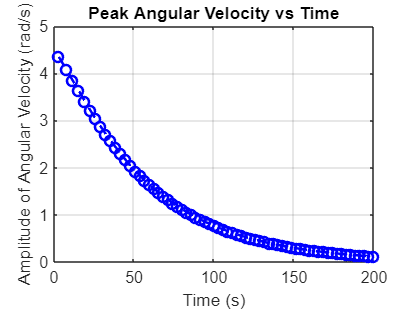


% Plot the peaks to visually inspect damping in angular velocity
figure;
plot(ttheta(locs_velocity), amplitudes_velocity, 'bo--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude of Angular Velocity (rad/s)');
title('Peak Angular Velocity vs Time');


grid on;

function rdot = eome(ttheta, rtheta) %Rtheta simply stands for r, used rtheta to avoid giving the same name with previous code for Q1

m = 1; %mass in kg
l = 2;  %length in m
g = 9.81; %acceleration due to gravity in m/s
d = 0.05 ; % 5% damping 
kstar = d*2*sqrt(m*m*(g/l));  %damping coefficient First formula found  

%The formula wasn't working, so I tried another formula
 k1 =  ((-log(1-d))/pi)*2*sqrt(m*m*g/l) ;
% and made iterations until my answers
%were as close as possible to 5%
k = 0.0749;
H = -k/(m*l) ;
K = -g/l ;
rdot(1) = rtheta(2) ;
rdot(2) = H*rtheta(2) + K*sin(rtheta(1)) ;

rdot = rdot' ;
end

